% Load the training data 
data = load("D:\college\FYP\Scripts\Object_Detection\ACF\version\v2\signs_trainingData.mat");
trainingData = data.signs_trainingData;


% Create an imageDatastore using the files from the table.
imds = imageDatastore(trainingData.imageFilename);

% Create a boxLabelDatastore using the label columns from the table.
blds = boxLabelDatastore(trainingData(:,2:end));

% Combine the datastores.
ds = combine(imds, blds);

detector = yolov4ObjectDetector("tiny-yolov4-coco")

detector =   yolov4ObjectDetector with properties:

        Network: [1×1 dlnetwork]
    AnchorBoxes: {2×1 cell}
     ClassNames: {80×1 cell}
      InputSize: [416 416 3]
      ModelName: 'tiny-yolov4-coco'


detector.Network

ans =   dlnetwork with properties:

         Layers: [74×1 nnet.cnn.layer.Layer]
    Connections: [80×2 table]
     Learnables: [80×3 table]
          State: [38×3 table]
     InputNames: {'input_1'}
    OutputNames: {'conv_31'  'conv_38'}
    Initialized: 1

  View summary with summary.



% Specify the input size
inputSize = [224 224 3];

trainingDataForEstimation = transform(ds,@(data)preprocessData(data,inputSize));

numAnchors = 6;
[anchors, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors);
area = anchors(:,1).*anchors(:,2);
[~,idx] = sort(area,"descend");
anchors = anchors(idx,:);
anchorBoxes = {anchors(1:3,:);anchors(4:6,:)};


classes = {'TrafficSign'};
detector = yolov4ObjectDetector("tiny-yolov4-coco",classes,anchorBoxes,InputSize=inputSize);


options = trainingOptions("sgdm", ...
    InitialLearnRate=0.001, ...
    MiniBatchSize=16,...
    MaxEpochs=40, ...
    BatchNormalizationStatistics="moving",...
    ResetInputNormalization=false,...
    VerboseFrequency=30);


% Train the YOLO v4 network.
trainedDetector = trainYOLOv4ObjectDetector(ds,detector,options);

*************************************************************************
Training a YOLO v4 Object Detector for the following object classes:

* TrafficSign

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss
    _____    _________    ___________    _________    ____________
      2         30         00:01:33        0.001         3.7631   
      3         60         00:03:14        0.001         1.3641   
      4         90         00:05:29        0.001        0.85575   
      5         120        00:07:45        0.001        0.32732   
      6         150        00:10:01        0.001        0.42011   
      8         180        00:11:24        0.001        0.44608   
      9         210        00:12:47        0.001        0.25596   
     10         240        00:14:12        0.001        0.29126   

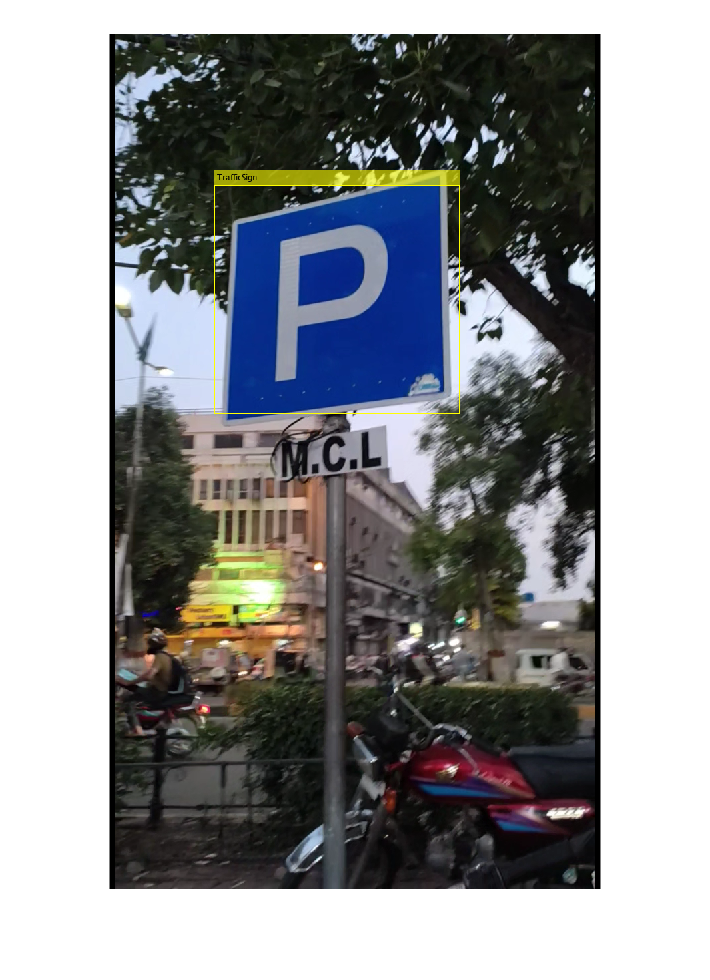

I = imread("D:\college\FYP\Scripts\Object_Detection\ACF\version\v2\ACF_Training_Data\parking_11_027.png");

[bboxes, scores, labels] = detect(trainedDetector,I,Threshold=0.05);
detectedImg = insertObjectAnnotation(I,"Rectangle",bboxes,labels);
figure
imshow(detectedImg)

function data = preprocessData(data,targetSize)
for num = 1:size(data,1)
    I = data{num,1};
    imgSize = size(I);
    bboxes = data{num,2};
    I = im2single(imresize(I,targetSize(1:2)));
    scale = targetSize(1:2)./imgSize(1:2);
    bboxes = bboxresize(bboxes,scale);
    data(num,1:2) = {I,bboxes};
end
end